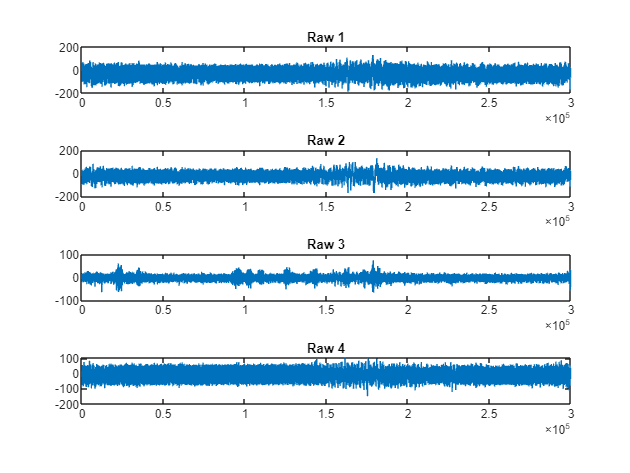

% 0. Read Data
[X_raw,directSignal] = edfECGRead("adfecgdb\r10.edf",1);

fs = 1000;
[ndt, ns]=size(X_raw);


% 1. Preprocessing

% Detrending

n=14;
D1 = detrend(X_raw(:,1),n); % removes the nth degree polynomial trend
D2 = detrend(X_raw(:,2),n);
D3 = detrend(X_raw(:,3),n);
D4 = detrend(X_raw(:,4),n);

%X_d = [D1 D2 D3 D4];
X_d = X_raw;

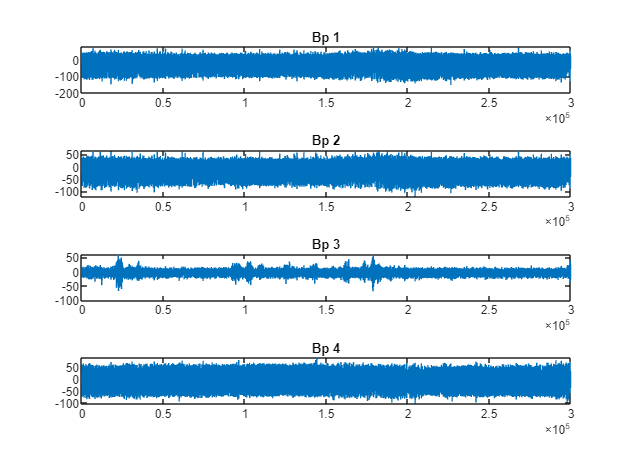

% Bandpass filtering
order = 2530;
[X_bp, delay_bp] = bandpassFilter(X_d,BandPassCutoff3Hz,order,1); 

% delay is not used throughout since signal is centred

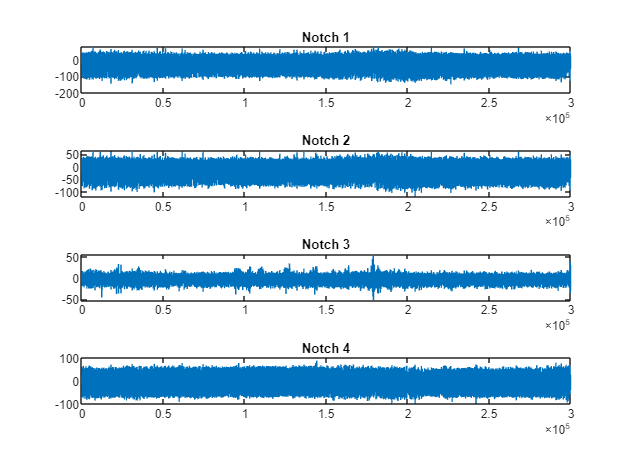

% Notch filtering
order = 786;
[X_nf, delay_nf] = notchFilter(X_bp,notchFilter50Hz,order,1);

% Impulse artefact cancellation
X_im=FecgImpArtCanc(X_nf,fs);

%{
sig1 = X_im(:,1);
sig2 = X_im(:,2);
sig3 = X_im(:,3);
sig4 = X_im(:,4);

sig1 = gnegate(sig1);
sig2 = gnegate(sig2);
sig3 = gnegate(sig3);
sig4 = gnegate(sig4);

X_im(:,1) = sig1;
X_im(:,2) = sig2;
X_im(:,3) = sig3;
X_im(:,4) = sig4;
%}

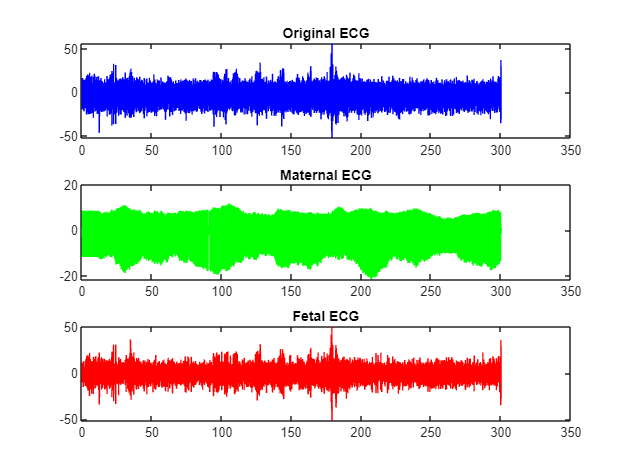

% 2. mECG cancellation

templateSize = 20;
windowTime = 0.029;
%{
[fecg1, mecg1, ~] = cancelMecgTrial(X_im(:,1), fs, templateSize,windowTime,0,0);
[fecg2, mecg2, ~] = cancelMecgTrial(X_im(:,2), fs, templateSize,windowTime,0,0);
[fecg3, mecg3, ~] = cancelMecgTrial(X_im(:,3), fs, templateSize,windowTime,0,0);
[fecg4, mecg4, delayValue] = cancelMecgTrial(X_im(:,4), fs, templateSize,windowTime,0,1);
%}
%{
[fecg1, mecg1] = cancelMecgAverage(X_im(:,1), fs, templateSize,0,0);
[fecg2, mecg2] = cancelMecgAverage(X_im(:,2), fs, templateSize,0);
[fecg3, mecg3] = cancelMecgAverage(X_im(:,3), fs, templateSize,0,1);
[fecg4, mecg4, delayValue] = cancelMecgAverage(X_im(:,4), fs, templateSize,0);
%}
[fecg1, mecg1] = cancelMecgCausalAverage(X_im(:,1), fs, templateSize,0,0);
[fecg2, mecg2] = cancelMecgCausalAverage(X_im(:,2), fs, templateSize,0);
[fecg3, mecg3] = cancelMecgCausalAverage(X_im(:,3), fs, templateSize,0,1);

[fecg4, mecg4, delayValue] = cancelMecgCausalAverage(X_im(:,4), fs, templateSize,0);
%{
[fecg1, mecg1] = cancelMecgCausal(X_im(:,1), fs, templateSize,0);
[fecg2, mecg2] = cancelMecgCausal(X_im(:,2), fs, templateSize,0);
[fecg3, mecg3] = cancelMecgCausal(X_im(:,3), fs, templateSize,0);
[fecg4, mecg4, delayValue] = cancelMecgCausal(X_im(:,4), fs, templateSize,0);
%}
%{
[fecg1, mecg1] = cancelMecgCausalSVD(X_im(:,1), fs, templateSize,0);
[fecg2, mecg2] = cancelMecgCausalSVD(X_im(:,2), fs, templateSize,0);
[fecg3, mecg3] = cancelMecgCausalSVD(X_im(:,3), fs, templateSize,0);
[fecg4, mecg4, delayValue] = cancelMecgCausalSVD(X_im(:,4), fs, templateSize,0);
%}
%{
[fecg1, mecg1] = cancelMecg(X_im(:,1), fs, templateSize,0);
[fecg2, mecg2] = cancelMecg(X_im(:,2), fs, templateSize,0);
[fecg3, mecg3] = cancelMecg(X_im(:,3), fs, templateSize,0);
[fecg4, mecg4, delayValue] = cancelMecg(X_im(:,4), fs, templateSize,0);
%}
%{    
[fecg1, mecg1, ~] = cancelMecgAvgSmooth(X_im(:,1), fs, templateSize,windowTime,0,0);
[fecg2, mecg2, ~] = cancelMecgAvgSmooth(X_im(:,2), fs, templateSize,windowTime,0,0);
[fecg3, mecg3, ~] = cancelMecgAvgSmooth(X_im(:,3), fs, templateSize,windowTime,0,0);
[fecg4, mecg4, delayValue] = cancelMecgAvgSmooth(X_im(:,4), fs, templateSize,windowTime,0,1);
%}

%qrsM=chanelSelection(X_im,fs);
%Xr=FecgQRSmCanc(X_im,qrsM,fs,'Name',1);
%plot(Xr(:,1))

% 3. ICA/Post-processing

% Try ICA for separating noise and signals of interest
Z = [fecg1, fecg2, fecg3, fecg4];
Z = transpose(Z);
r = 4;
[Zica, W, T, mu] = fastICA(Z,r);

***** Fast ICA (kurtosis) *****
Iter 001: max(1 - |<w001, w000>|) = 0.4289
Iter 002: max(1 - |<w002, w001>|) = 0.01281
Iter 003: max(1 - |<w003, w002>|) = 0.01299
Iter 004: max(1 - |<w004, w003>|) = 0.009227
Iter 005: max(1 - |<w005, w004>|) = 0.00499
Iter 006: max(1 - |<w006, w005>|) = 0.00232
Iter 007: max(1 - |<w007, w006>|) = 0.001878
Iter 008: max(1 - |<w008, w007>|) = 0.002015
Iter 009: max(1 - |<w009, w008>|) = 0.002463
Iter 010: max(1 - |<w010, w009>|) = 0.002512
Iter 011: max(1 - |<w011, w010>|) = 0.001567
Iter 012: max(1 - |<w012, w011>|) = 0.0006125
Iter 013: max(1 - |<w013, w012>|) = 0.0001814
Iter 014: max(1 - |<w014, w013>|) = 4.812e-05
Iter 015: max(1 - |<w015, w014>|) = 1.501e-05
Iter 016: max(1 - |<w016, w015>|) = 5.548e-06
Iter 017: max(1 - |<w017, w016>|) = 2.356e-06
Iter 018: max(1 - |<w018, w017>|) = 1.108e-06
Iter 019: max(1 - |<w019, w018>|) = 5.545e-07




ica1 = Zica(1,:);
ica2 = Zica(2,:);
ica3 = Zica(3,:);
ica4 = Zica(4,:);

% 4. F1 calculation
compareSignal = ica4;
delayedDirect = delayseq(directSignal,delayValue);
[f1, estimatedR, directR] = compare(compareSignal,delayedDirect,1000);
estimRTrain = zeros([1 length(estimatedR)]);
directRTrain = zeros([1 length(directR)]);
f1=f1

f1 = 0.4954

% Plots

% Plot ica results
%{
subplot(4,1,1);
plot(ica1)
title('ica 1')

subplot(4,1,2);
plot(ica2)
title('ica 2')

subplot(4,1,3);
plot(ica3)
title('ica 3')

subplot(4,1,4);
plot(ica4)
title('ica 4')
%}

% mECG plots
%{
subplot(4,1,1);
plot(mecg1)
title('mECG 1')
    
subplot(4,1,2); 
plot(mecg2)
title('mECG 2')  

subplot(4,1,3); 
plot(mecg3)
title('mECG 3')
   
subplot(4,1,4); 
plot(mecg4)
title('mECG 4')
%}

% fECG plots
%{
subplot(4,1,1);
plot(fecg1)
title('fECG 1')
    
subplot(4,1,2); 
plot(fecg2)
title('fECG 2')  

subplot(4,1,3); 
plot(fecg3)
title('fECG 3')
   
subplot(4,1,4); 
plot(fecg4)
title('fECG 4')
%}

%{
subplot(4,1,1);
plot(X_im(:,1))
title('Imp 1')
    
subplot(4,1,2); 
plot(X_im(:,2))
title('Imp 2')  

subplot(4,1,3); 
plot(X_im(:,3))
title('Imp 3')
   
subplot(4,1,4); 
plot(X_im(:,4))
title('Imp 4')
%}